% 清除内容
clear all
clc

# task1

灰度图像的字典学习模型及算法

将参考示例代码，将他的功能封装成一个函数，输入灰度图片，和相应的参数，得到它对应的字典D,以及每步的误差有多大

%参数设置
p = [1, 1]* 9; % size of dictionary atoms
nA = prod(p); % number of Atoms
gap = 4; % control the overlapping
lambda = 50; % regularization parameter
tol = 1e-4; 
maxits = 1e4; % maximum number of interation

np = prod(p); % number of pixels in each patch
n = size(noise_image, 1:2);

函数或变量 'noise_image' 无法识别。

I = [1:gap:n(1)-p(1), n(1)-p(1)+1];
J = [1:gap:n(2)-p(2), n(2)-p(2)+1];
nP = numel(I)* numel(J); % total number of patches

lP = zeros(nP, 5); % location of each patch




000500, time: 04.02s, rel_error: 4.29e-04, obj_value: 7.98e+07...
001000, time: 08.16s, rel_error: 1.92e-04, obj_value: 5.71e+07...
001500, time: 12.32s, rel_error: 1.68e-04, obj_value: 4.13e+07...
002000, time: 16.41s, rel_error: 1.90e-04, obj_value: 3.01e+07...
002500, time: 20.52s, rel_error: 1.66e-04, obj_value: 2.22e+07...
003000, time: 24.62s, rel_error: 2.22e-04, obj_value: 1.63e+07...
003500, time: 28.71s, rel_error: 1.97e-04, obj_value: 1.20e+07...
004000, time: 32.83s, rel_error: 1.92e-04, obj_value: 8.87e+06...
004500, time: 36.89s, rel_error: 2.67e-04, obj_value: 6.25e+06...
005000, time: 40.98s, rel_error: 2.37e-04, obj_value: 4.22e+06...
005500, time: 45.07s, rel_error: 2.43e-04, obj_value: 2.93e+06...
006000, time: 49.17s, rel_error: 2.81e-04, obj_value: 1.94e+06...
006500, time: 53.25s, rel_error: 2.29e-04, obj_value: 1.41e+06...
007000, time: 57.33s, rel_error: 1.22e-04, obj_value: 1.26e+06...


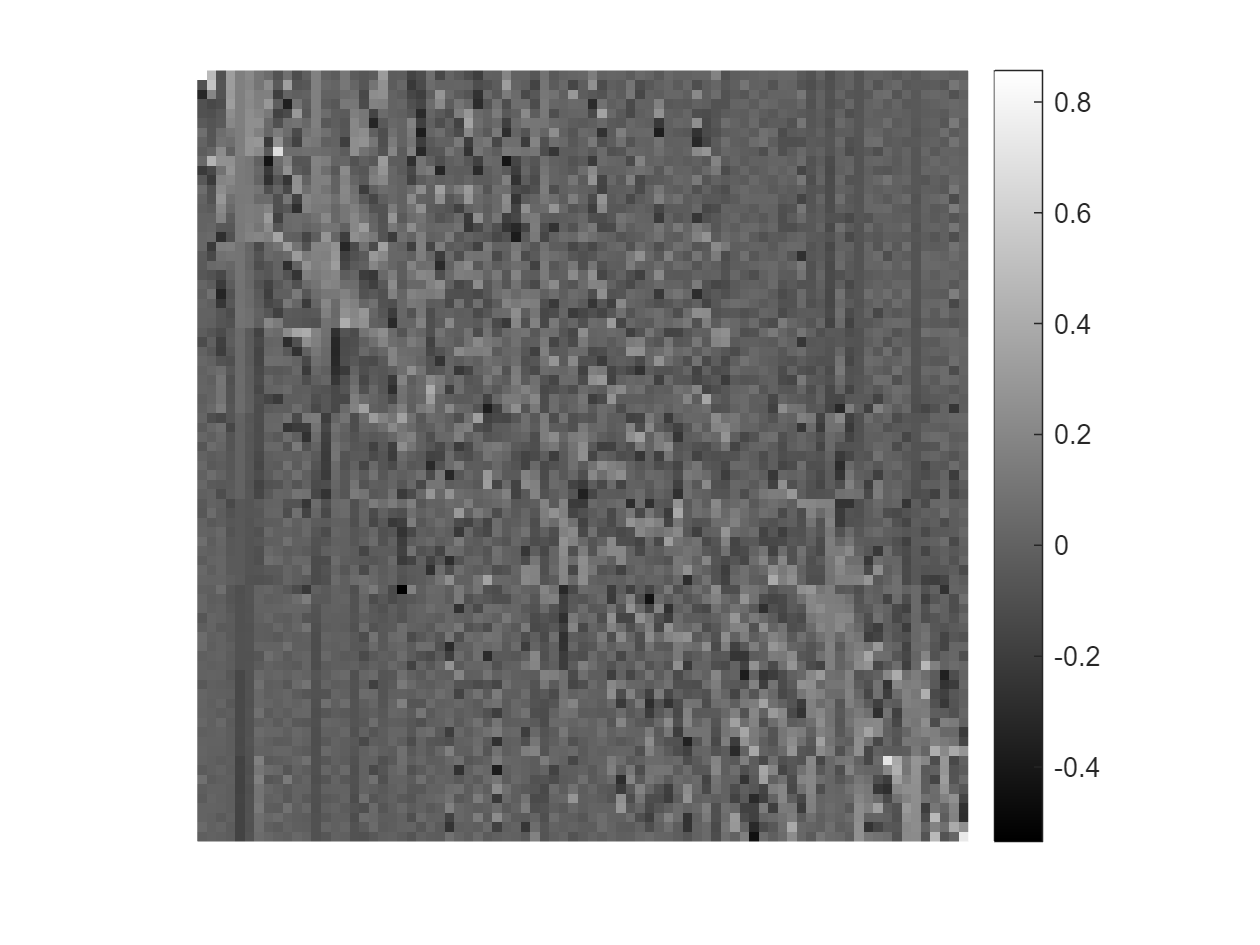

[D_barbara, ek_barbara] = gray_image_dictionary('filename','lena_512.png', 'tolerance', tol, 'max_iterations', maxits);      

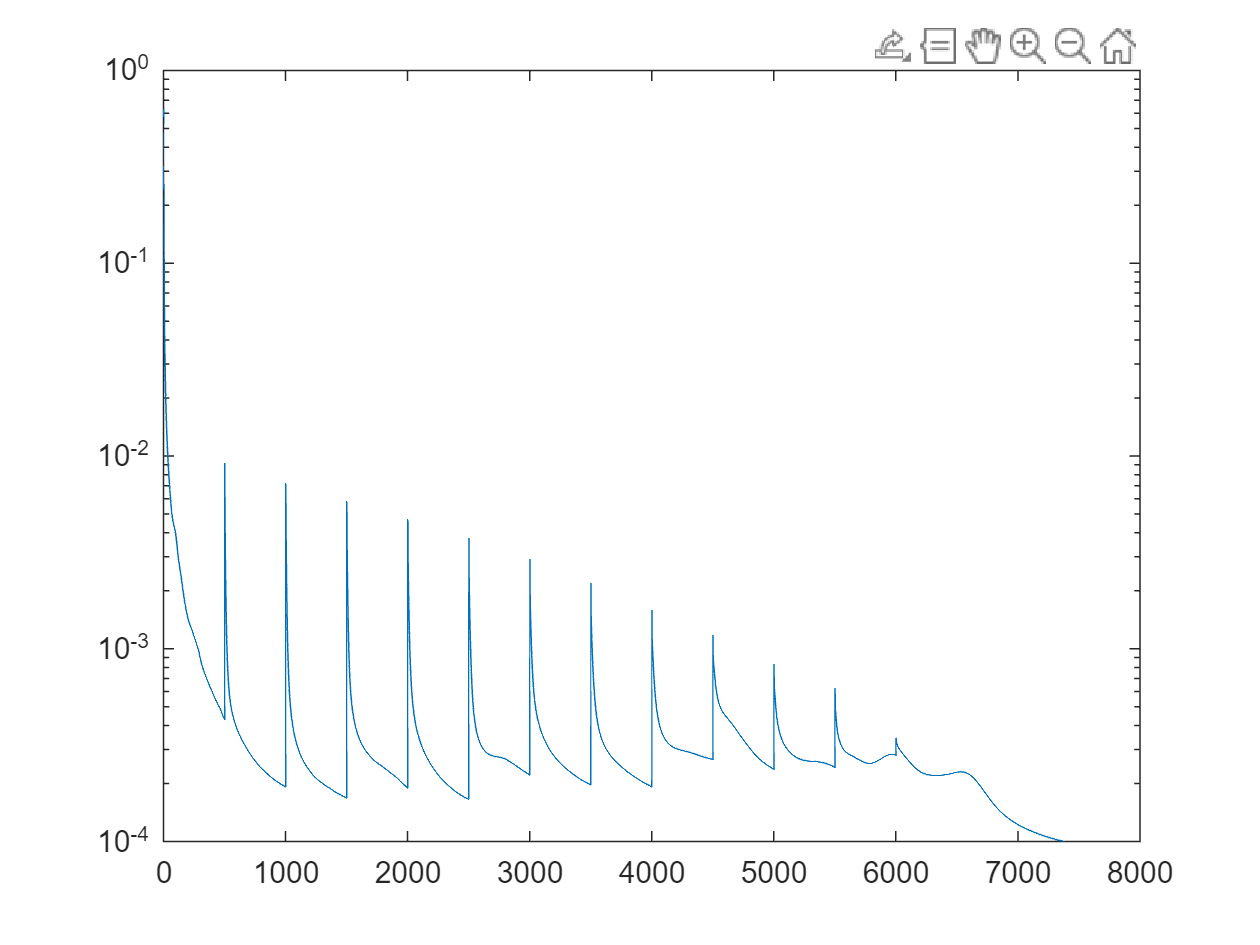

fprintf('\n');
figure(002), clf;
semilogy(ek_barbara);

# Task2

彩色图像的字典学习模型及算法

000500, time: 03.82s, rel_error: 4.36e-04, obj_value: 6.75e+07...
001000, time: 07.56s, rel_error: 2.25e-04, obj_value: 4.62e+07...
001500, time: 11.27s, rel_error: 2.10e-04, obj_value: 3.17e+07...
002000, time: 15.02s, rel_error: 1.65e-04, obj_value: 2.18e+07...
002500, time: 18.71s, rel_error: 2.16e-04, obj_value: 1.50e+07...
003000, time: 22.42s, rel_error: 1.84e-04, obj_value: 1.03e+07...
003500, time: 26.14s, rel_error: 2.08e-04, obj_value: 7.05e+06...
004000, time: 29.81s, rel_error: 1.88e-04, obj_value: 4.83e+06...
004500, time: 33.46s, rel_error: 1.50e-04, obj_value: 3.32e+06...
005000, time: 37.15s, rel_error: 1.62e-04, obj_value: 2.23e+06...
005500, time: 40.82s, rel_error: 1.64e-04, obj_value: 1.42e+06...
006000, time: 44.55s, rel_error: 1.29e-04, obj_value: 9.73e+05...
006500, time: 48.16s, rel_error: 1.21e-04, obj_value: 8.15e+05...
007000, time: 51.86s, rel_error: 1.08e-04, obj_value: 7.60e+05...
000500, time: 03.68s, rel_error: 4.12e-04, obj_value: 8.40e+07...
001000, ti

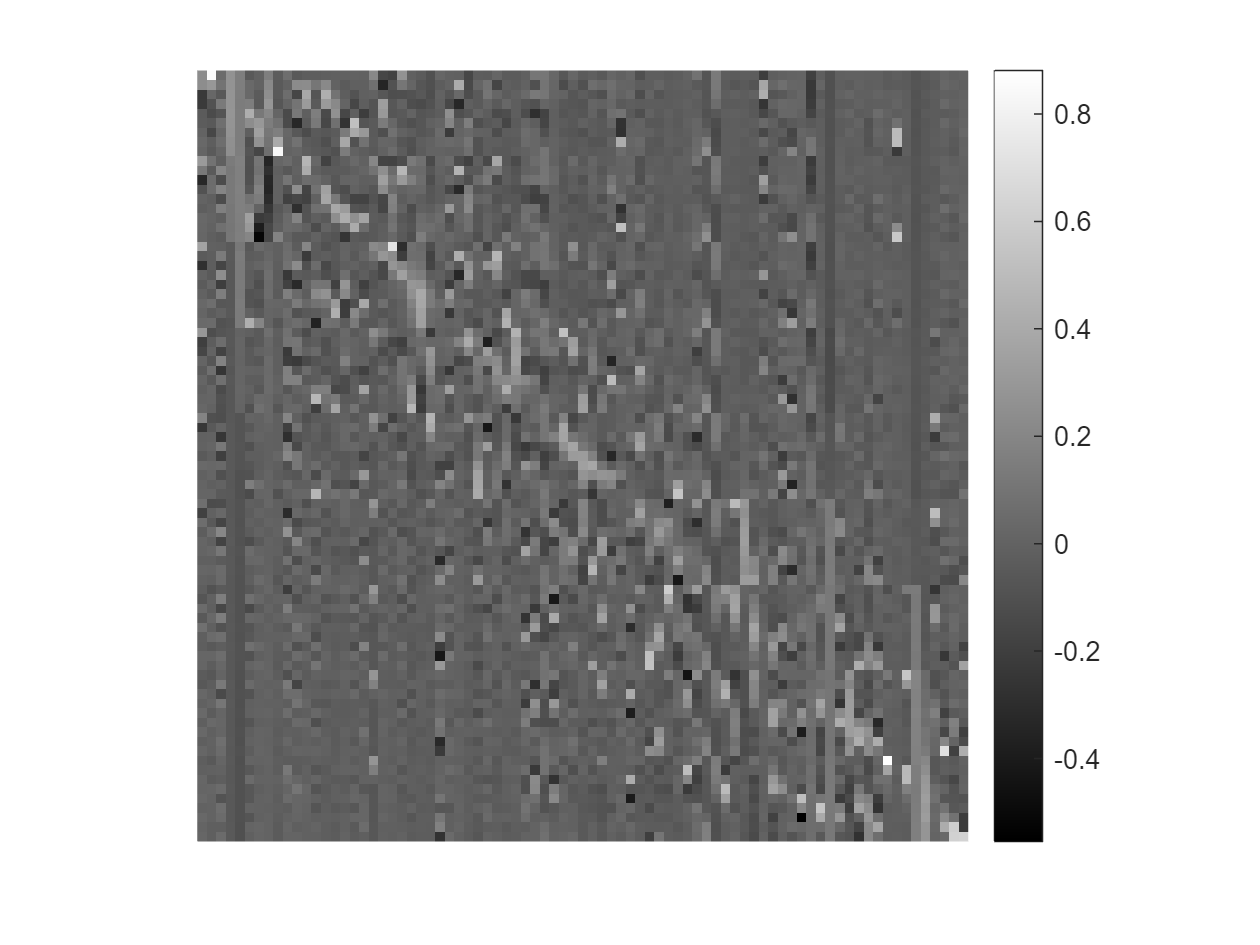

[D_McM12, ek_McM12] = color_image_dictionary('filename','McM12.tif', 'tolerance', tol, 'max_iterations', maxits);

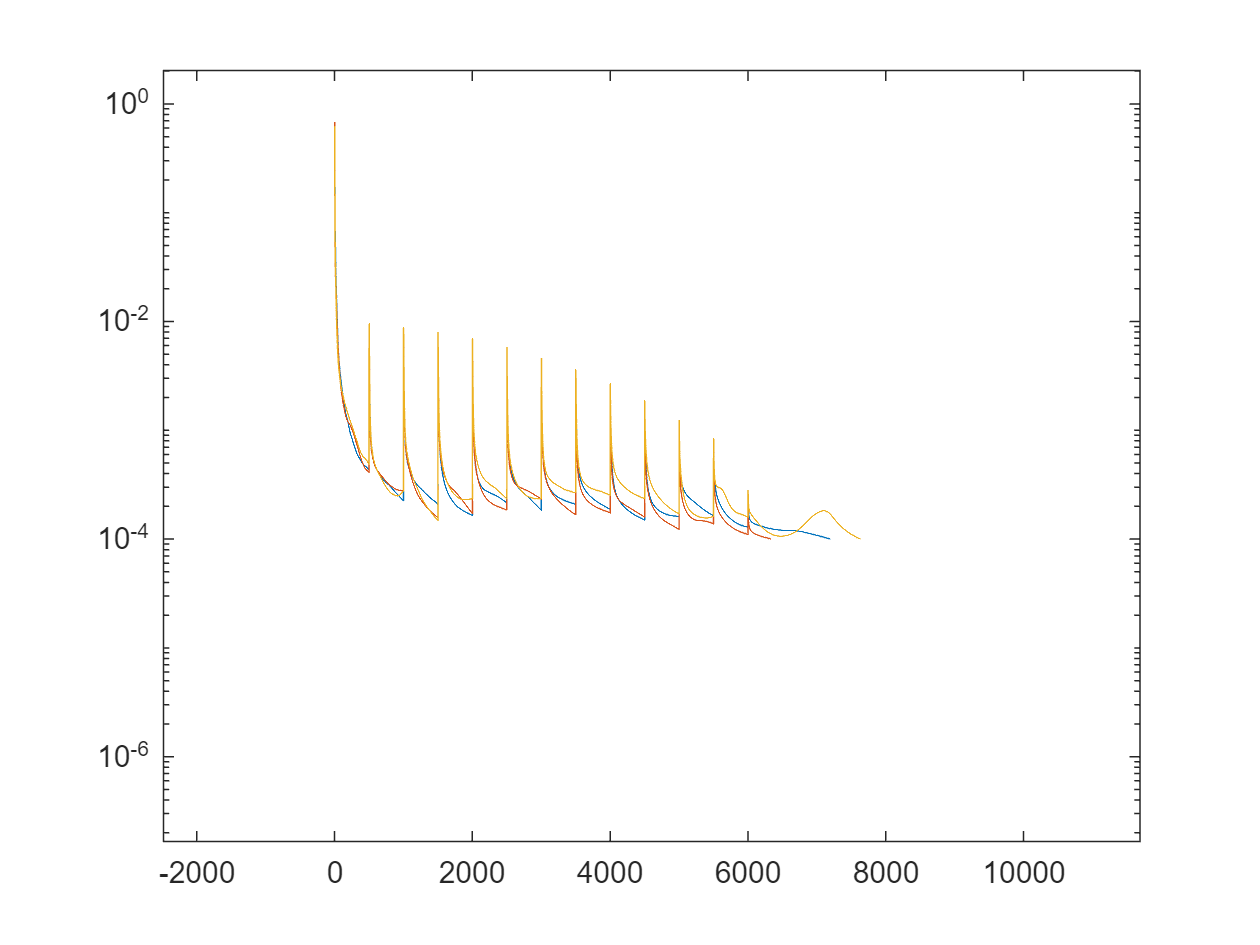

fprintf('\n');
figure(002), clf;
semilogy(ek_McM12);

# 彩色图片RGB通道的字典

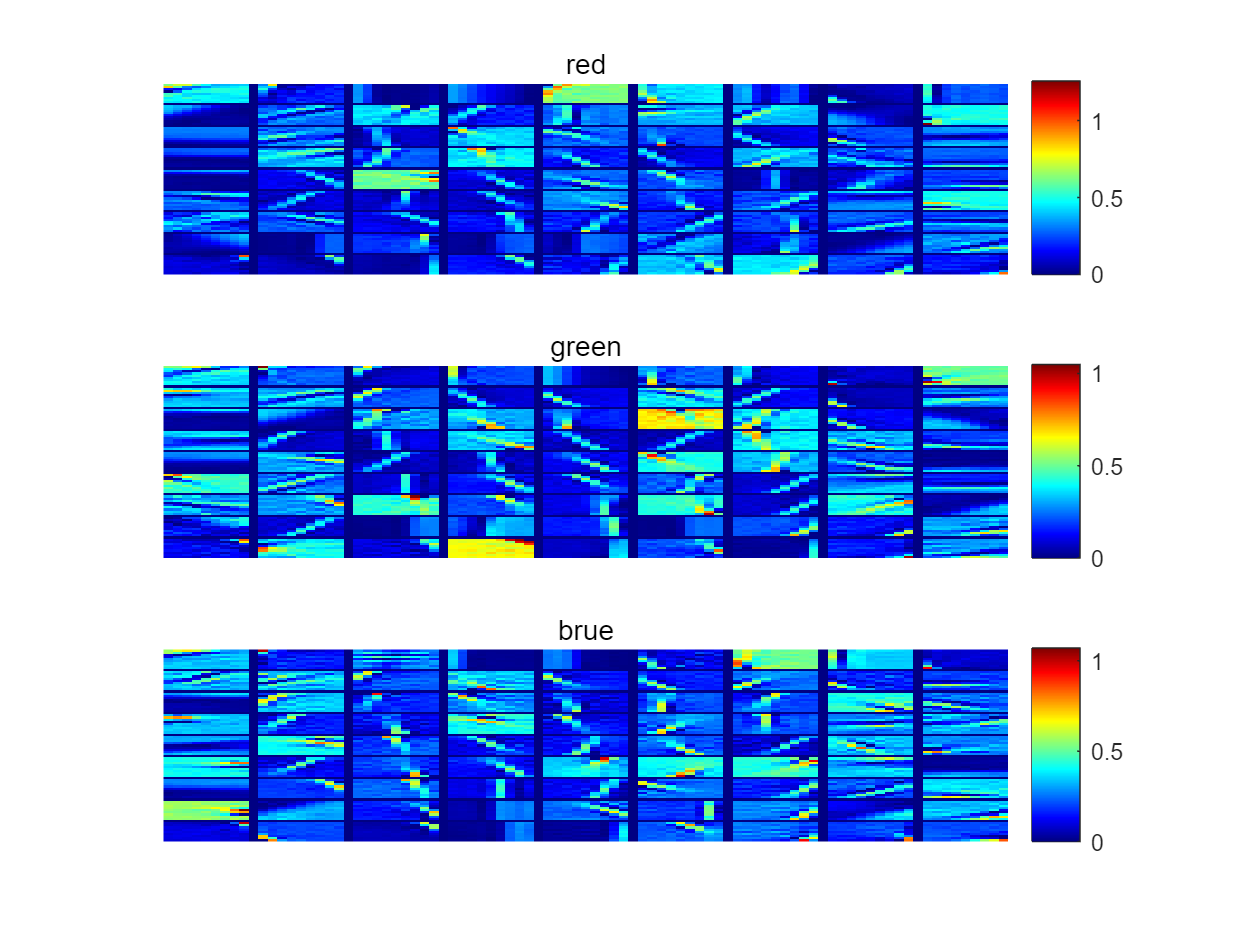

i_size = prod(p) + p(1) - 1;
imD = zeros(i_size, i_size);
title_name = {'red', 'green', 'brue'};
figure(2); clf;
hold on
for k=1:3
    c = 0;
    for i=1: p(1)
        range_i = (i-1)*(p(1)+1) + 1 : i*(p(1)+1)-1;
        for j = 1: p(2)
            c = c + 1;

            range_j = (j-1)*(p(2)+1) + 1 : j*(p(2)+1)-1;

            atom = D_McM12(:, c, k);
            imD(range_i, range_j) = reshape(atom, p) - min(atom(:));
        end
    end
    subplot(3,1,k);
    imagesc(imD);
    colormap(jet);
    axis off;
    colorbar;
    title(title_name{1,k});
end
hold off

# Task3 降噪

对18张图进行学习，利用学习到的词典进行降噪

load McM12_noise.mat u_n
McM12_noise = u_n;
load D_McM12.mat D_McM12

[C, ek_lasso, mP_noise] = image_denoise('noise_image', McM12_noise, 'dictionary', D_McM12);

Max difference between the values of patch mean value: 251.55...
000500, rel_error: 4.93e+00, obj_value: 2.6282e+08, l1_norm: 1.40e+08...
001000, rel_error: 1.02e+00, obj_value: 2.6292e+08, l1_norm: 1.40e+08...
001500, rel_error: 1.46e+00, obj_value: 2.6295e+08, l1_norm: 1.40e+08...
002000, rel_error: 2.58e-01, obj_value: 2.6299e+08, l1_norm: 1.40e+08...
002500, rel_error: 1.73e-01, obj_value: 2.6300e+08, l1_norm: 1.40e+08...
003000, rel_error: 1.17e-01, obj_value: 2.6301e+08, l1_norm: 1.40e+08...
003500, rel_error: 6.43e-02, obj_value: 2.6301e+08, l1_norm: 1.40e+08...
004000, rel_error: 4.78e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
004500, rel_error: 3.53e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
005000, rel_error: 2.59e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
005500, rel_error: 2.07e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
006000, rel_error: 1.97e-02, obj_value: 2.6303e+08, l1_norm: 1.40e+08...
006500, rel_error: 1.41e-02, obj_value: 2.6303e+08, l1_norm

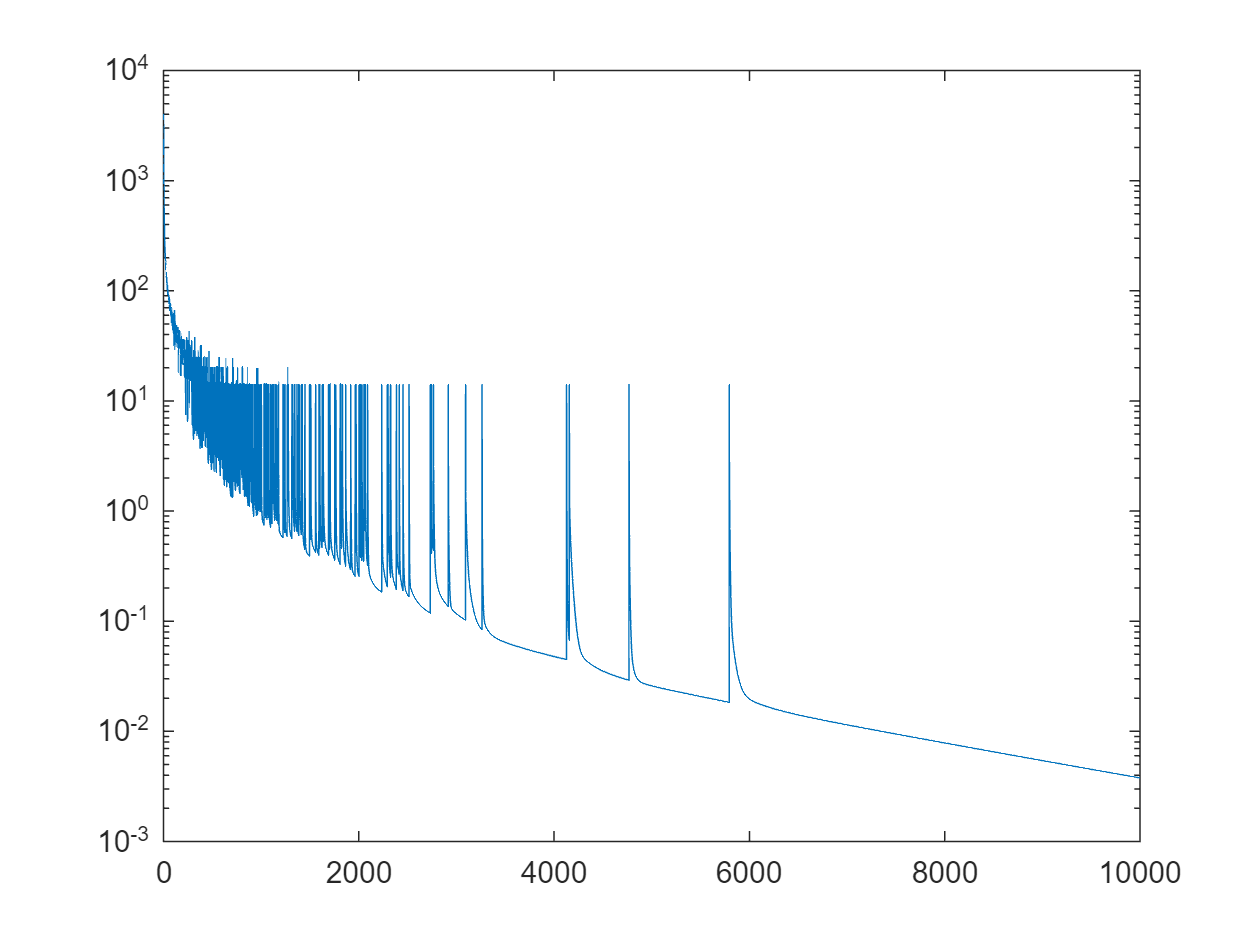

figure(006), clf;
semilogy(ek_lasso);

y = D_McM12(:,:,1)* C;
Y = 0* McM12_noise(:,:,1);
W = 0* McM12_noise(:,:,1);

for i=1:nP
    p_location = lP(i, 2:5);
    patch = y(:, i) + mP_noise(i); % - mean(patch(:));

    range_i = p_location(1):p_location(2);
    range_j = p_location(3):p_location(4);

    Y(range_i, range_j) = Y(range_i, range_j) + reshape(patch, p);
    W(range_i, range_j) = W(range_i, range_j) + 1;
end

函数或变量 'nP' 无法识别。


u_denoise = Y./W;



figure(007), clf;
imgsc(u_denoise);
title(sprintf('PSNR = %.2f', psnr(u, u_denoise)));







